images\seashell_five.jpg


ans = 0.7300

ans = 0.0356

ans = 0.6144

ans = 0.0374

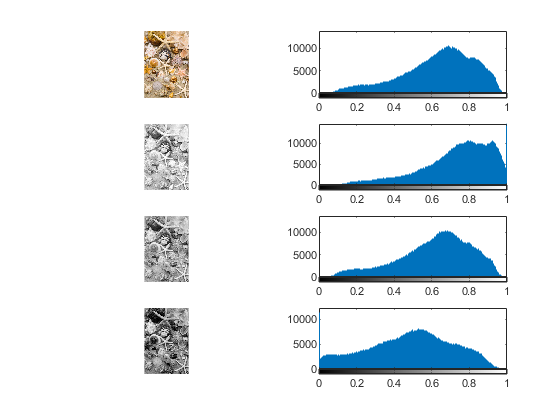

ans = 0.4806

ans = 0.0520

images\shellfish_four.jpg


ans = 0.8254

ans = 0.0365

ans = 0.7788

ans = 0.0494

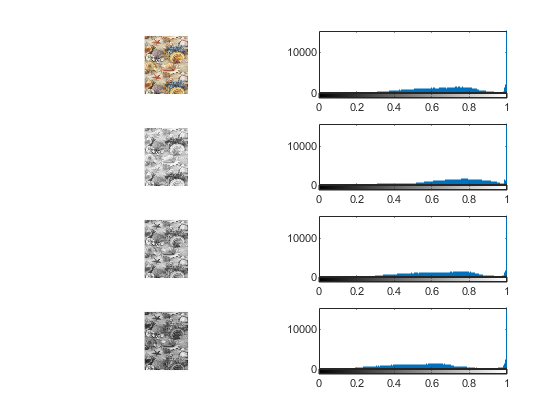

ans = 0.7196

ans = 0.0701

images\starfish.jpg


ans = 0.9234

ans = 0.0152

ans = 0.8892

ans = 0.0183

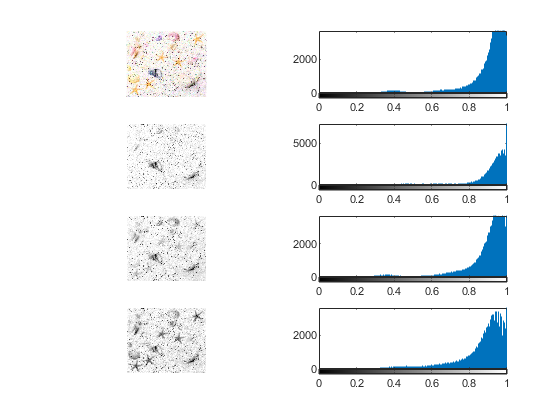

ans = 0.8619

ans = 0.0230

images\starfish_17.jpg


ans = 0.6869

ans = 0.0416

ans = 0.5477

ans = 0.0737

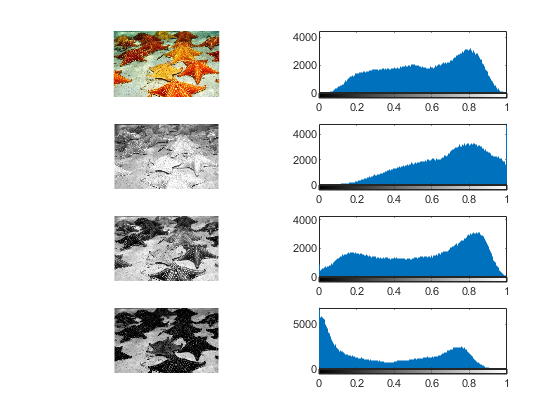

ans = 0.3494

ans = 0.0885

images\starfish_5.jpg


ans = 0.6373

ans = 0.0300

ans = 0.6679

ans = 0.0161

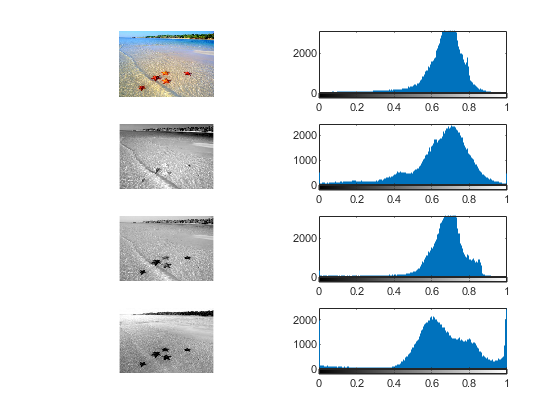

ans = 0.6643

ans = 0.0378

images\starfish_map0.jpg


ans = 0.9621

ans = 0.0029

ans = 0.9364

ans = 0.0039

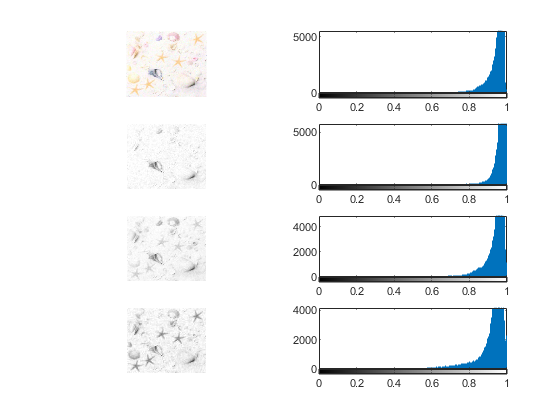

ans = 0.9166

ans = 0.0065

images\starfish_map1.jpg


ans = 0.9314

ans = 0.0095

ans = 0.8550

ans = 0.0189

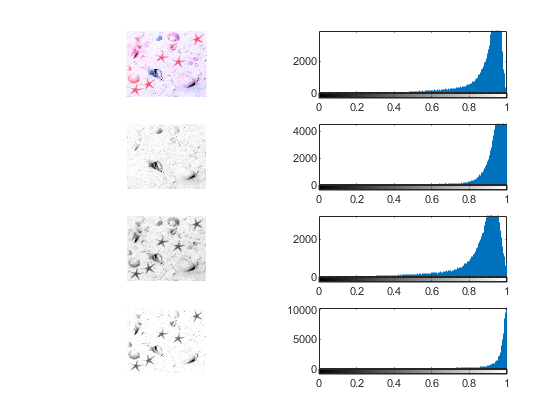

ans = 0.9485

ans = 0.0132

images\starfish_map2.jpg


ans = 0.9599

ans = 0.0055

ans = 0.9707

ans = 0.0053

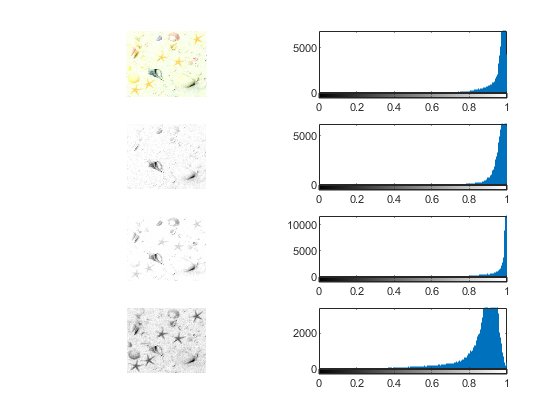

ans = 0.8614

ans = 0.0134

images\starfish_map3.jpg


ans = 0.9456

ans = 0.0059

ans = 0.8701

ans = 0.0082

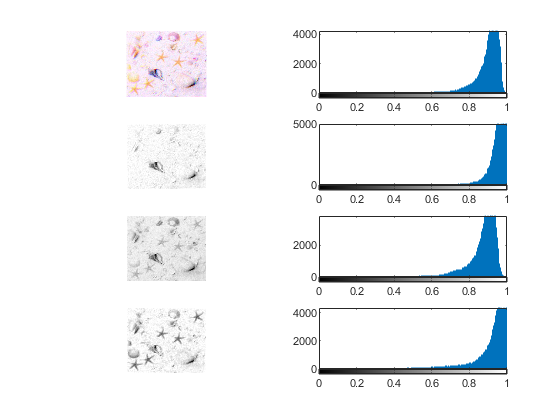

ans = 0.9149

ans = 0.0123

images\starfish_noise1.jpg


ans = 0.9299

ans = 0.0064

ans = 0.9004

ans = 0.0087

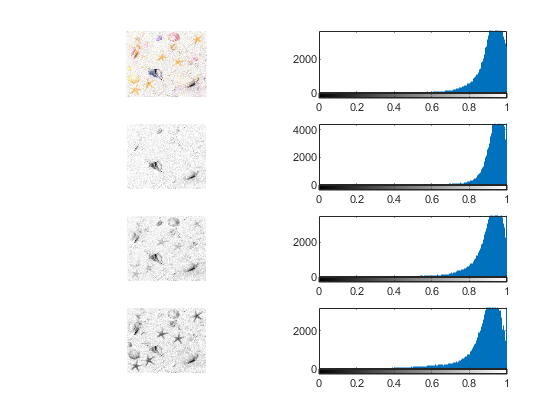

ans = 0.8734

ans = 0.0138

images\starfish_noise10.jpg


ans = 0.8604

ans = 0.0144

ans = 0.8429

ans = 0.0165

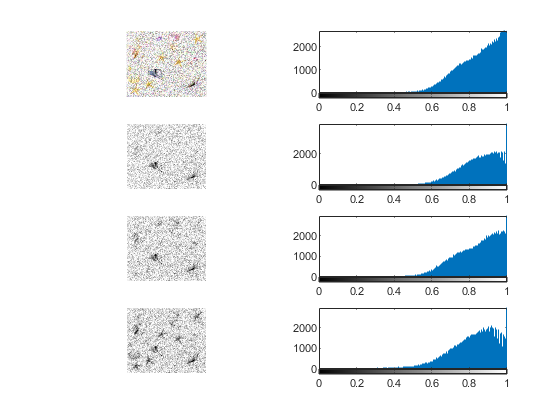

ans = 0.8216

ans = 0.0199

images\starfish_noise2.jpg


ans = 0.8704

ans = 0.0150

ans = 0.8496

ans = 0.0175

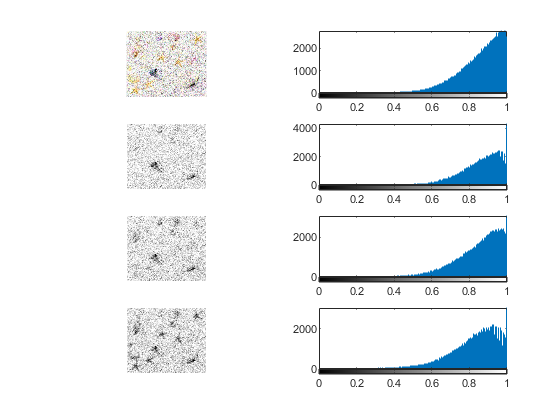

ans = 0.8261

ans = 0.0214

images\starfish_noise3.jpg


ans = 0.9353

ans = 0.0088

ans = 0.9017

ans = 0.0111

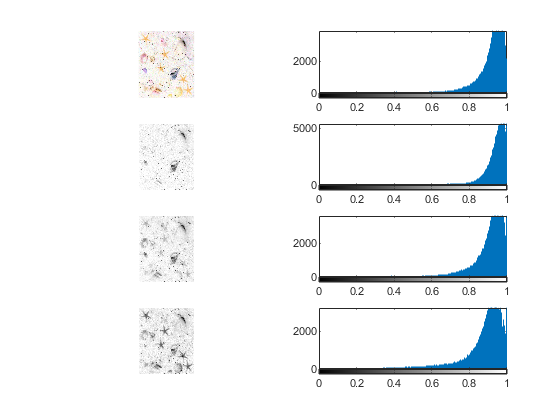

ans = 0.8736

ans = 0.0161

images\starfish_noise4.jpg


ans = 0.9152

ans = 0.0154

ans = 0.8853

ans = 0.0182

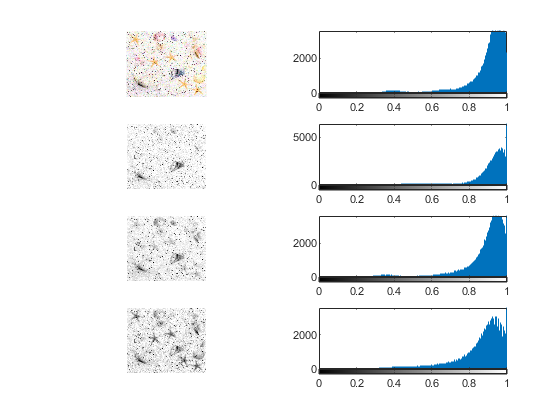

ans = 0.8568

ans = 0.0223

images\starfish_noise5.jpg


ans = 0.8645

ans = 0.0318

ans = 0.8419

ans = 0.0369

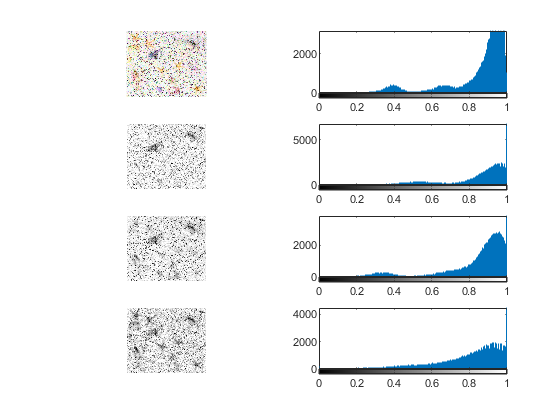

ans = 0.8131

ans = 0.0368

images\starfish_noise6.jpg


ans = 0.9328

ans = 0.0062

ans = 0.9027

ans = 0.0083

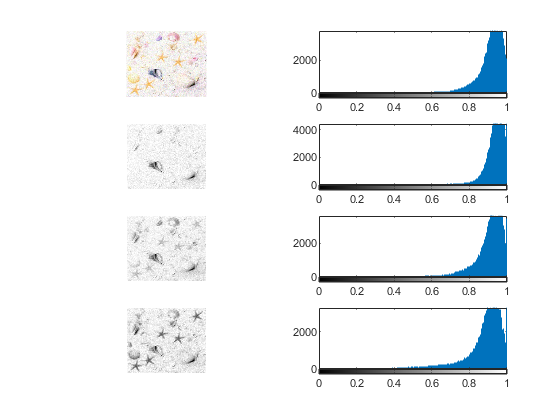

ans = 0.8755

ans = 0.0136

images\starfish_noise7.jpg


ans = 0.9019

ans = 0.0081

ans = 0.8890

ans = 0.0107

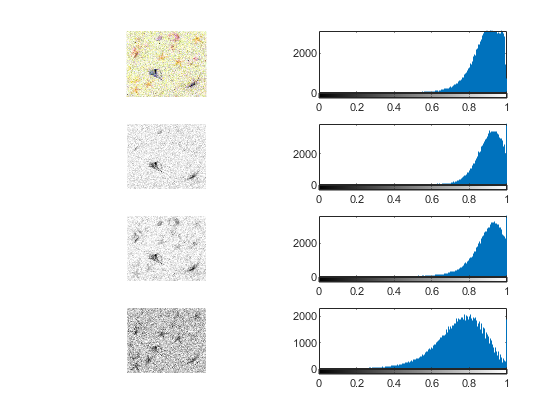

ans = 0.7443

ans = 0.0190

images\starfish_noise8.jpg


ans = 0.9252

ans = 0.0071

ans = 0.8991

ans = 0.0093

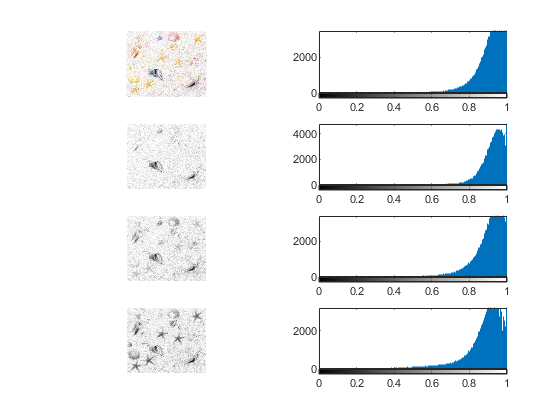

ans = 0.8737

ans = 0.0142

images\starfish_noise9.jpg


ans = 0.8303

ans = 0.0198

ans = 0.8169

ans = 0.0224

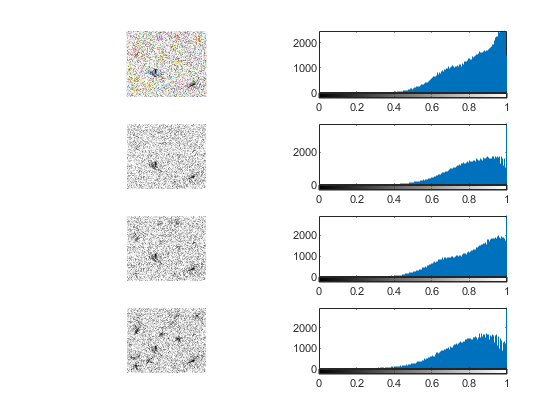

ans = 0.7966

ans = 0.0245

images\starfish_overlaid.jpg


ans = 0.2384

ans = 0.1190

ans = 0.1129

ans = 0.0366

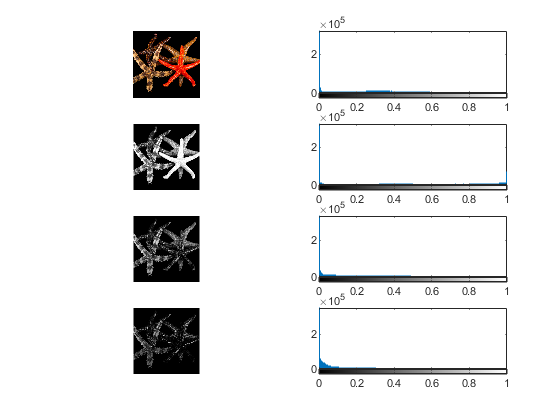

ans = 0.0597

ans = 0.0158

clear 
files = GetFilesInSubDir("images");

r = 4;
c = 2;
for i = 1:numel(files)
    filepath = files(i);
    
    disp(filepath)
    
    im = imread(filepath);
    
    im = rgb2hsv(im);
%     im = im2double(im);
    [ch1, ch2, ch3] = imsplit(im);
    
    figure
    subplot(r,c,1);
    imshow(im)
    subplot(r,c,2);
    allChHist = imhist(rgb2gray(im));
    imhist(rgb2gray(im))
    
    subplot(r,c,3);
    imshow(ch1)
    subplot(r,c,4);
    ch1Hist = imhist(ch1);
    imhist(ch1)
    mean2(ch1(:))
    var(ch1(:))
    
    subplot(r,c,5);
    imshow(ch2)
    subplot(r,c,6);
    ch2Hist = imhist(ch2);
    imhist(ch2)
    mean2(ch2(:))
    var(ch2(:))
    
    subplot(r,c,7);
    imshow(ch3)
    subplot(r,c,8);
    ch3Hist = imhist(ch3);
    imhist(ch3)
    mean2(ch3(:))
    var(ch3(:))
end

function filepaths = GetFilesInSubDir(subDir)
    files = dir(subDir);
    files = files(~ismember({files.name}, {'.', '..'})); % Remove navigation elements from struct.
    filepaths = subDir + "\" + {files.name};
end

